# maoyang / 206221321

Stu_ID = '206221321';

## 路径与课程数据

script_dir = fileparts(mfilename('fullpath'));
if isempty(script_dir), script_dir = pwd; end
addpath(fullfile(script_dir,'helpers'));
ess_week1_setup(script_dir);
case_dir = fullfile(script_dir,'data');
profiles = load(fullfile(case_dir,'profiles_24h.mat'));
price_MWh = profiles.price_MWh(:);
price_kWh = profiles.price_kWh(:);
T = numel(price_MWh); dt = 1;
assert(T==24 && all(price_MWh>0),'检查典型日分时电价。');
out_dir = fullfile(script_dir,'day2_results');
if ~isfolder(out_dir), mkdir(out_dir); end

## 参数与两类模型

P_rated = 2.0; E_rated = 2.0;
eta_ch = 0.90; eta_dis = 0.95;
SoC_0 = 0.50; SoC_min = 0.10; SoC_max = 1.00;
yalmip('clear');
LP = solve_storage(price_MWh,P_rated,E_rated,eta_ch,eta_dis,...
    SoC_0,SoC_min,SoC_max,dt,false);
MILP = solve_storage(price_MWh,P_rated,E_rated,eta_ch,eta_dis,...
    SoC_0,SoC_min,SoC_max,dt,true);
Comparison = table(["LP";"MILP"],[string(LP.Solver);string(MILP.Solver)],...
    [LP.Revenue_Yuan;MILP.Revenue_Yuan],...
    [LP.MaxSimultaneousPower_MW;MILP.MaxSimultaneousPower_MW],...
    [LP.TerminalSoCError;MILP.TerminalSoCError],...
    'VariableNames',{'Model','Solver','DailyRevenue_Yuan',...
    'MaxSimultaneousPower_MW','TerminalSoCError'});
disp(Comparison);

    Model        Solver       DailyRevenue_Yuan    MaxSimultaneousPower_MW    TerminalSoCError
    ______    ____________    _________________    _______________________    ________________

    "LP"      "linprog"            1553.6                     0                      0        
    "MILP"    "intlinprog"         1553.6                     0                      0        



assert(abs(LP.Revenue_Yuan-MILP.Revenue_Yuan)<0.01,'LP与MILP最优收益不一致。');

## 功率与容量灵敏度：每次只改变一项

P_values = [0.5;1;2;4];
E_values = [1;2;4;8];
P_revenue = zeros(size(P_values)); E_revenue = zeros(size(E_values));
for k = 1:numel(P_values)
    if P_values(k)==P_rated
        trial=MILP;
    else
        trial=solve_storage(price_MWh,P_values(k),E_rated,eta_ch,eta_dis,...
            SoC_0,SoC_min,SoC_max,dt,true);
    end
    P_revenue(k)=trial.Revenue_Yuan;
end
for k = 1:numel(E_values)
    if E_values(k)==E_rated
        trial=MILP;
    else
        trial=solve_storage(price_MWh,P_rated,E_values(k),eta_ch,eta_dis,...
            SoC_0,SoC_min,SoC_max,dt,true);
    end
    E_revenue(k)=trial.Revenue_Yuan;
end
PowerSensitivity=table(P_values,repmat(E_rated,size(P_values)),P_revenue,...
    'VariableNames',{'Power_MW','Energy_MWh','DailyRevenue_Yuan'});
EnergySensitivity=table(repmat(P_rated,size(E_values)),E_values,E_revenue,...
    'VariableNames',{'Power_MW','Energy_MWh','DailyRevenue_Yuan'});
disp(PowerSensitivity); disp(EnergySensitivity);

    Power_MW    Energy_MWh    DailyRevenue_Yuan
    ________    __________    _________________

      0.5           2              1118.3      
        1           2              1263.4      
        2           2              1553.6      
        4           2              1553.6      

    Power_MW    Energy_MWh    DailyRevenue_Yuan
    ________    __________    _________________

       2            1               776.8      
       2            2              1553.6      
       2            4              2526.8      
       2            8              4473.2      



assert(all(diff(P_revenue)>=-0.01) && all(diff(E_revenue)>=-0.01),...
    '灵敏度收益不应随可行域扩大而降低。');

## 逐时结果与能量核对

Hourly=table((1:T)',price_kWh,MILP.P_ch_MW,MILP.P_dis_MW,...
    MILP.P_dis_MW-MILP.P_ch_MW,MILP.SoC,...
    price_MWh.*(MILP.P_dis_MW-MILP.P_ch_MW)*dt,...
    'VariableNames',{'Period','Price_YuanPerKWh','Charge_MW','Discharge_MW',...
    'NetDischarge_MW','SoC','NetRevenue_Yuan'});
RoundTripEfficiency=eta_ch*eta_dis;
SaleAfter1MWhCharge=RoundTripEfficiency;
fprintf('充入1 MWh电量后可售出 %.3f MWh；往返效率 %.1f%%。\n',...
    SaleAfter1MWhCharge,100*RoundTripEfficiency);

充入1 MWh电量后可售出 0.855 MWh；往返效率 85.5%。


fprintf('MILP日收益 %.6f 元；充电量 %.6f MWh；售电量 %.6f MWh。\n',...
    MILP.Revenue_Yuan,MILP.ChargeEnergy_MWh,MILP.DischargeEnergy_MWh);

MILP日收益 1553.593778 元；充电量 4.000000 MWh；售电量 3.420000 MWh。


Day2=struct('StudentID',Stu_ID,'CourseCommit',...
    '1d34d745ee234be0d27d8790dc95d687538fab2b',...
    'Power_MW',P_rated,'Energy_MWh',E_rated,'EtaCharge',eta_ch,...
    'EtaDischarge',eta_dis,'SoC0',SoC_0,'SoCMin',SoC_min,'SoCMax',SoC_max,...
    'TimeStep_h',dt,'Price_YuanPerMWh',price_MWh,'LP',LP,'MILP',MILP,...
    'Comparison',Comparison,'Hourly',Hourly,'PowerSensitivity',PowerSensitivity,...
    'EnergySensitivity',EnergySensitivity,'SaleAfter1MWhCharge_MWh',SaleAfter1MWhCharge);
writetable(Comparison,fullfile(out_dir,'Day2_LP_MILP_206221321.csv'));
writetable(Hourly,fullfile(out_dir,'Day2_Hourly_206221321.csv'));
writetable(PowerSensitivity,fullfile(out_dir,'Day2_PowerSensitivity_206221321.csv'));
writetable(EnergySensitivity,fullfile(out_dir,'Day2_EnergySensitivity_206221321.csv'));
save(fullfile(out_dir,'maoyang_206221321_Day2.mat'),'Day2');
summary_file=fullfile(script_dir,'result_summary.mat');
if isfile(summary_file), save(summary_file,'Day2','-append');
else, save(summary_file,'Day2'); end

## 任务二结果图

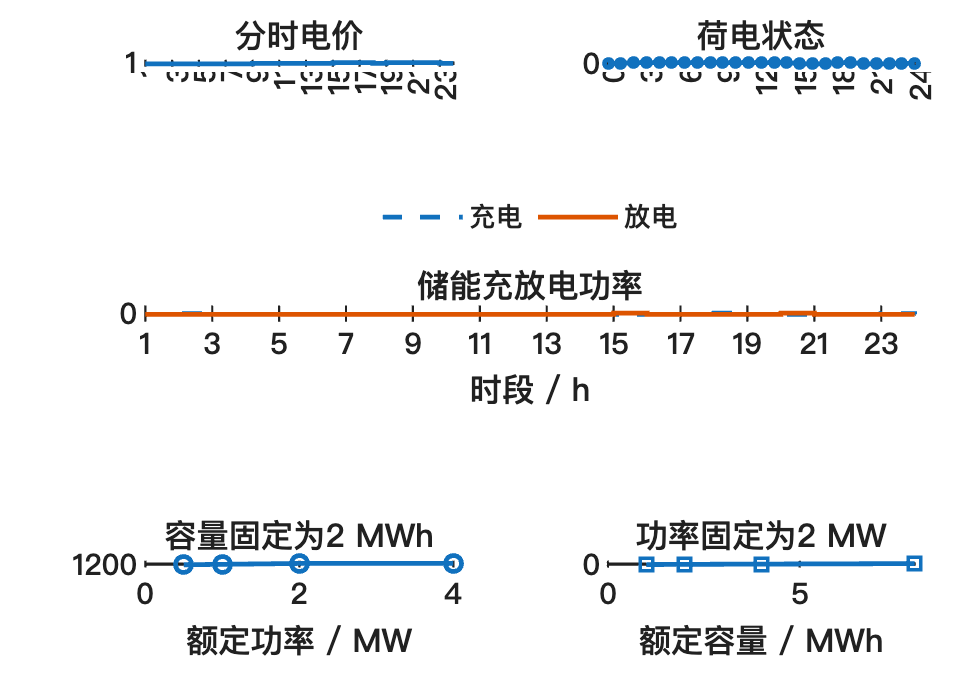

ess_week1_figure(2,struct('Day2',Day2),script_dir);


validation=struct('Completed',true,'Revenue_Yuan',MILP.Revenue_Yuan,...
    'LPDifference_Yuan',abs(LP.Revenue_Yuan-MILP.Revenue_Yuan),...
    'MaxEnergyError_MWh',MILP.MaxEnergyError_MWh,...
    'MaxSimultaneousPower_MW',MILP.MaxSimultaneousPower_MW,...
    'TerminalSoCError',MILP.TerminalSoCError,'YALMIP',which('yalmip'));
writelines(jsonencode(validation),fullfile(out_dir,'validation.json'));

function s=solve_storage(price,Pmax,Emax,eta_ch,eta_dis,s0,smin,smax,dt,use_binary)
T=numel(price);
pc=sdpvar(T,1,'full');pd=sdpvar(T,1,'full');soc=sdpvar(T,1,'full');
constraints=[0<=pc<=Pmax,0<=pd<=Pmax,smin<=soc<=smax,soc(T)==s0];
previous=[s0;soc(1:end-1)];
constraints=[constraints,soc==previous+(eta_ch*pc-pd/eta_dis)*dt/Emax];
if use_binary
    u=binvar(T,1,'full');
    constraints=[constraints,pc<=u*Pmax,pd<=(1-u)*Pmax];
    kind='MILP';
else
    kind='LP';
end
objective=sum(price(:).*(pc-pd))*dt;
[sol,solver,seconds]=ess_live_solve(constraints,objective,kind);
assert(sol.problem==0,'求解未成功：%s',sol.info);
s=struct('Model',kind,'Solver',solver,'SolveSeconds',seconds,...
    'P_ch_MW',value(pc),'P_dis_MW',value(pd),'SoC',value(soc),...
    'Revenue_Yuan',-value(objective),'SolverStatus',sol.problem);
s.MaxSimultaneousPower_MW=max(min(s.P_ch_MW,s.P_dis_MW));
s.TerminalSoCError=abs(s.SoC(end)-s0);
s.MaxEnergyError_MWh=max(abs(Emax*(s.SoC-[s0;s.SoC(1:end-1)])-...
    (eta_ch*s.P_ch_MW-s.P_dis_MW/eta_dis)*dt));
s.PowerLimitViolation_MW=max([0;-s.P_ch_MW;-s.P_dis_MW;s.P_ch_MW-Pmax;s.P_dis_MW-Pmax]);
s.ChargeEnergy_MWh=sum(s.P_ch_MW)*dt;
s.DischargeEnergy_MWh=sum(s.P_dis_MW)*dt;
assert(s.TerminalSoCError<1e-6 && s.MaxEnergyError_MWh<1e-6 &&...
    s.PowerLimitViolation_MW<1e-5 && min(s.SoC)>=smin-1e-6 &&...
    max(s.SoC)<=smax+1e-6,'储能约束核对未通过。');
if use_binary
    s.ChargeState=value(u);
    s.IntegerError=max(abs(s.ChargeState-round(s.ChargeState)));
    assert(s.MaxSimultaneousPower_MW<1e-6 && s.IntegerError<1e-6,'充放电互斥核对未通过。');
end
assert(abs(s.DischargeEnergy_MWh-eta_ch*eta_dis*s.ChargeEnergy_MWh)<1e-6,...
    '全天能量守恒核对未通过。');
end